clear all;
% h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\EEA List\20080326.001_bc_15sec-energyFlux.h5';
% h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\Temp\20101018.001_bc_2min-energyFlux.h5';
h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\Temp\20080326.001_bc_15sec-energyFlux_v85.h5';
omniH5FileStr = 'G:\My Drive\Research\Projects\Data\omni.h5';

## Load data

dascData = get_2D_plot_inputs_time_independent(h5FileStr,...
    'plotModeStr','OpticalImage');
time = dascData.time;

timeMinIndx = find_time(time,'26-Mar-2008 11:00');
timeMaxIndx = find_time(time,'26-Mar-2008 11:30');

pfisrData = get_2D_plot_inputs_time_independent(h5FileStr,...
    'plotModeStr','EnergyFluxMap');

PFISR Energy Flux Map projected at 85.1506 km



ibeam = 13;
energySlice = 100; %keV

k=1;
probeLat = pfisrData.latitude(ibeam,1);
probeLon = pfisrData.longitude(ibeam,1);
multiWaitbar('Calculating...',0);
id = 1/(timeMaxIndx-timeMinIndx+1);
for itime = timeMinIndx:timeMaxIndx
    try
    tempData = get_2D_plot_inputs_at_time(h5FileStr,...
        'plotModeStr','OpticalImage',...
        'thisTimeIndx',itime);
    image=tempData.image;
    latitude = dascData.latitude;
    longitude = dascData.longitude;
    nanFlags = isnan(latitude) | isnan(longitude) | isnan(image);
    latitude(nanFlags) = [];
    longitude(nanFlags) = [];
    image(nanFlags) = [];
    F= scatteredInterpolant(latitude(:),longitude(:),image(:),'linear','none');
%     tempPixel = [F(probeLat,probeLon), F(probeLat,probeLon+0.05), F(probeLat+0.05,probeLon),...
%         F(probeLat-0.05,probeLon), F(probeLat,probeLon-0.5), F(probeLat,probeLon)];
%     pixels(k)=sum(tempPixel(:))./5;
    pixels(k) = F(probeLat,probeLon);
    thisTimeDASC(k)=tempData.thisTime;
    
    timePfisrIndx = find_time(pfisrData.time,datestr(dascData.time(itime))); 
    tempPfisrData = get_2D_plot_inputs_at_time(h5FileStr,...
        'plotModeStr','EnergyFluxMap',...
        'thisTimeIndx',timePfisrIndx);
    
%     energyFlux(k) = interp1(pfisrData.zEnergyBin(ibeam,:),tempPfisrData.diffEnergyFlux(ibeam,:),energySlice*1000);
    energyFlux(k) = trapz(pfisrData.zEnergyBin(ibeam,:),tempPfisrData.diffEnergyFlux(ibeam,:));
    thisTimePFISR(k)=tempPfisrData.thisTime;   
    multiWaitbar('Calculating...','Increment',id);    
    k=k+1;
    catch ME;
    end   
end
multiWaitbar('Calculating...',1);    
multiWaitbar('CLOSEALL');

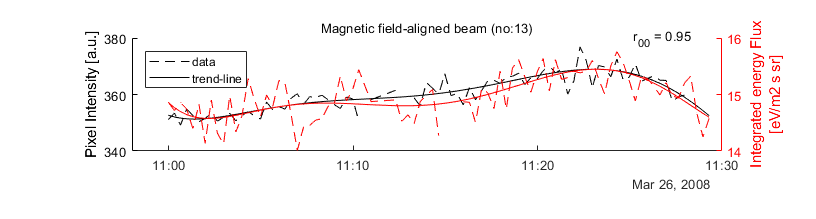

pixels1=pixels;
pixels1(pixels>450)=nan;
pixels1(pixels<300)=nan;
energyFlux1=energyFlux;
energyFlux1(energyFlux<10^12) = nan;
energyFlux2 = interp1(thisTimePFISR,energyFlux1,thisTimeDASC);
fenergy=log10(energyFlux2);
durtn = (thisTimeDASC-floor(thisTimeDASC))*24*60*60;
fPixel=fit(durtn(~isnan(pixels1))',pixels1(~isnan(pixels1))','poly6');
fEnergy=fit(durtn(~isnan(fenergy))',fenergy(~isnan(fenergy))','poly6');

pixelMovingAverage = conv(pixels1,ones(5,1)/5,'same');
energyMovingAverage = conv(fenergy,ones(5,1)/5,'same');

totalPanelNo=1;

hFig=figure(1);

clf
p=panel();
p.pack(1);

panelSize = 30; %in mm
demargin = 4;
panelDefinition=cell(1,totalPanelNo);
for i=1:1:totalPanelNo
    panelDefinition(i)={{panelSize}}; 
end
p(1).pack(panelDefinition);

p.marginleft=35;
p.marginright=25;
p.margintop=10;
p(1).de.margin=demargin;
% p.fontsize=12;
p.select('all');
timeMinStr='2008-03-26/08:05:00';
timeMaxStr='2008-03-26/12:55:00';
DateNumBeg=datenum(timeMinStr);
DateNumEnd=datenum(timeMaxStr);
timeTick=0.5;
  
resize_figure(hFig, panelSize*totalPanelNo+4*(totalPanelNo+1)+20);

q=p(1);

q(1).select();
yyaxis left
plot(datetime(datestr(thisTimeDASC)),pixels1,'--k');
ylabel('Pixel Intensity [a.u.]');
ax1=gca;
ax1.YColor='k';
hold on;
plot(datetime(datestr(thisTimeDASC)),fPixel(durtn),'-k');
% plot(datetime(datestr(thisTimeDASC(5:end-5))),pixelMovingAverage(5:end-5),'-');
yyaxis right
plot(datetime(datestr(thisTimeDASC)),log10(energyFlux2),'--r');
ax2=gca;
ax2.YColor='r';
ylabel({'Integrated energy Flux', '[eV/m2 s sr]'});
hold on;
plot(datetime(datestr(thisTimeDASC)),fEnergy(durtn),'-r');
% plot(datetime(datestr(thisTimeDASC(5:end-5))),energyMovingAverage(5:end-5),'-');
title('Magnetic field-aligned beam (no:13)');
pixels2=pixels1;
pixels2(isnan(pixels2))=0;
energyFlux3=energyFlux2;
energyFlux3(isnan(energyFlux3))=10;
r=xcorr(pixels2,log10(energyFlux3),0,'coeff');
text(0.85,1,['r_0_0 = ',num2str(r,2)],'Units','normalized');
legend('data','trend-line','Location','northwest');